# Homework #2

## Kurt Delegard

## PHYS 434 AB

Which is more probable when rolling 2 six-sided dice: rolling snake eyes (two ones) or rolling sevens (dice sum to seven)?

For each die, one has a 1/6 chance of rolling any of the 6 values. Following the rule that $P\left(A\;\mathrm{and}\;B\right)=P\left(A\right)*P\left(B\right)$, and given that for any value of either die $P\left(A\right)=P\left(B\right)=\frac{1}{6}$, we can determine that any combination of two die values (e.g. 2 and 6, 1 and 3, 5 and 5) will have a 1/36 chance of occuring.

There is only one combination that will yield two ones: throwing two ones. No other combination of die values will sum to 2. Thus we can infer that the probability of throwing snake eyes is 1/36.

However, there are several ways to roll two dice such that their values sum to 7: 

1 + 6

ans = 7

2 + 5

ans = 7

3 + 4

ans = 7

4 + 3

ans = 7

5 + 2

ans = 7

6 + 1

ans = 7

Since there are three options that yield a sum of seven, we can say that the probability of rolling a sum of seven is 6/36 = 1/6.

Therefore, it is more probable to roll a sum of seven than it is to roll snake eyes. The ratio of their probabilities is 

(1/6) / (1/36)

ans = 6

2. Probability of sum of 2 6-sided dice

Each die has values {1 2 3 4 5 6}. 

Each of these values has probability [1/6 1/6 1/6 1/6 1/6 1/6].

A system of two dice has values {2 3 4 5 6 7 8 9 10 11 12}.

To find the probabilities for each of these values, one can use the discrete convolution equation: $P_{A+B} \left(x\right)=\sum_z P_A \left(z\right)*P_B \left(x-z\right)$.

x can take any value from 1-12 from our system of two dice, while z can range from 1-6 for either of the individual dice.

For example, we will find the probability of rolling a sum of 1:


$$P_{A+B} \left(1\right)=\sum_z P_A \left(z\right)*P_B \left(1-z\right)$$


Now we will sum over all values of z, starting with 1:


$$P_A \left(1\right)*P_B \left(1-1\right)=P_A \left(1\right)*P_B \left(0\right)=0$$


There is zero probability of rolling a zero on any die. Furthermore, if we increase z any more, we will end up with a term $P_B \left(-1\right)$; there is also zero probability of rolling any negative number. Therefore, the probability of rolling a sum of 1 with two dice is zero.

For two dice:


$$P_{A+B} \left(2\right)=\sum_z P_A \left(z\right)*P_B \left(2-z\right)$$


Summing over values of z, starting with 1:


$$P_A \left(2\right)*P_B \left(2-1\right)=P_A \left(2\right)*P_B \left(1\right)=\frac{1}{6}*\frac{1}{6}=\frac{1}{36}$$



$$P_A \left(2\right)*P_B \left(2-2\right)=P_A \left(2\right)*P_B \left(0\right)=0$$


The sum terminates after 1 iteration - the probability of rolling a sum of 2 is 1/36.

The rest of these probabilities can be calculated by hand, but here I will calculate them individually using for loops:

prob = 1/6;
prob_sums = zeros(1, 13);

for x = 2:12
    for z = 1:6
        if x-z > 0 & x-z <= 6
            prob_sums(x) = prob_sums(x) + prob*prob;
        else 
            continue
        end
    end
end
disp(prob_sums);

         0    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1389    0.1111    0.0833    0.0556    0.0278         0



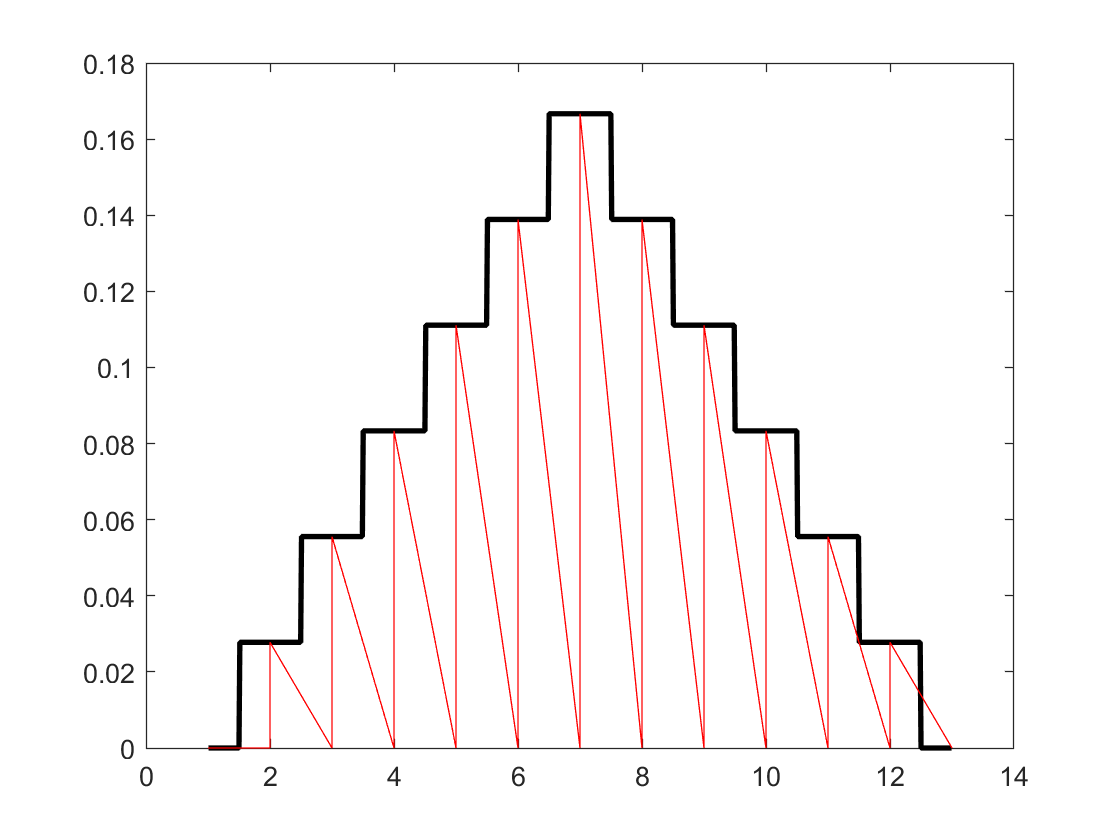


clf;
xq = linspace(0, 14, 1000);
vq = interp1(1:13, prob_sums, xq, 'nearest');
plot(xq, vq, 'k-', 'linewidth', 2), hold on;
xlines = 1:26;
xlines(1:2:26) = 1:13;
xlines(2:2:26) = 1:13;
ylines = 1:26;
ylines(1:2:26) = zeros(1, 13);
ylines(2:2:26) = prob_sums;

for jj = 1:25
    plot([xlines(jj), xlines(jj+1)], [ylines(jj), ylines(jj+1)], 'r-'), hold on;
end